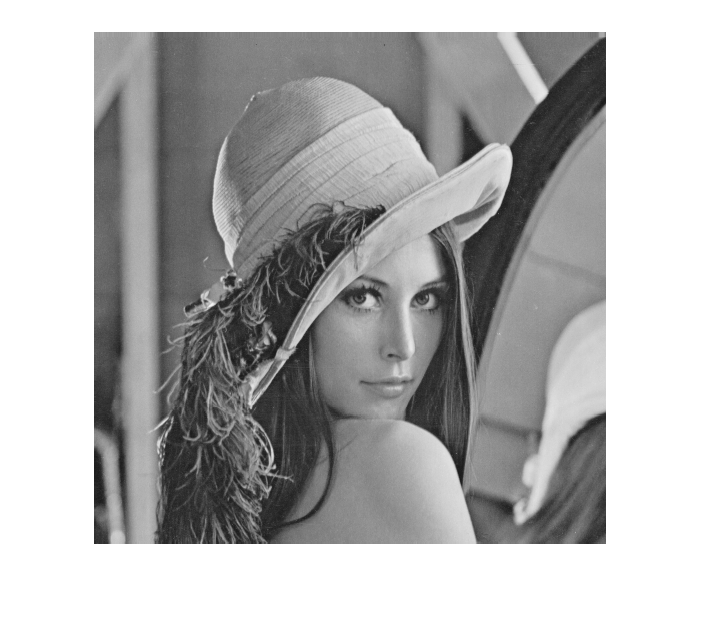

close all;
clear; clc;
key = 'qwertyuiopasdfghjklzxcvbnm123456';
I = imread('in/lena.bmp');
w = imread('in/sdust.bmp');
imshow(I);

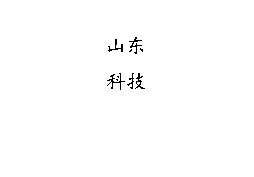

imshow(w);

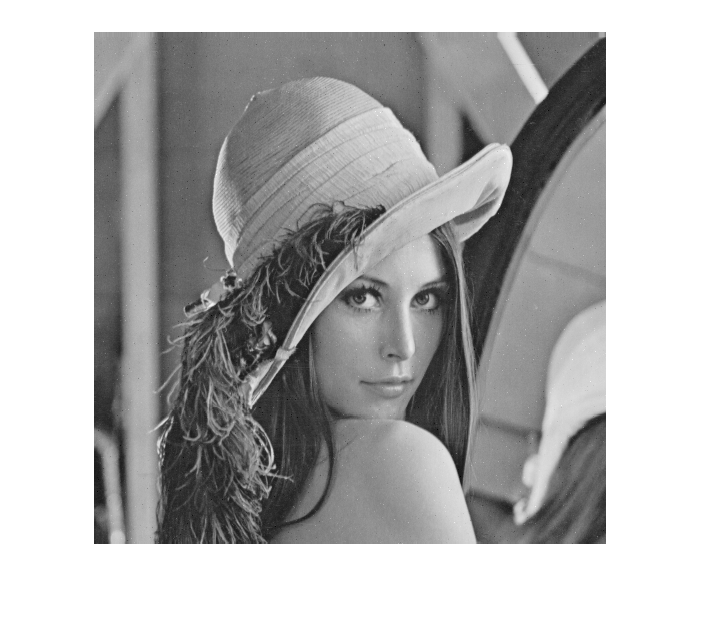

I1 = embedded_watermark(I, w, key);
imshow(I1);

w1 = extract_watermark(I1, key);
imshow(w1);

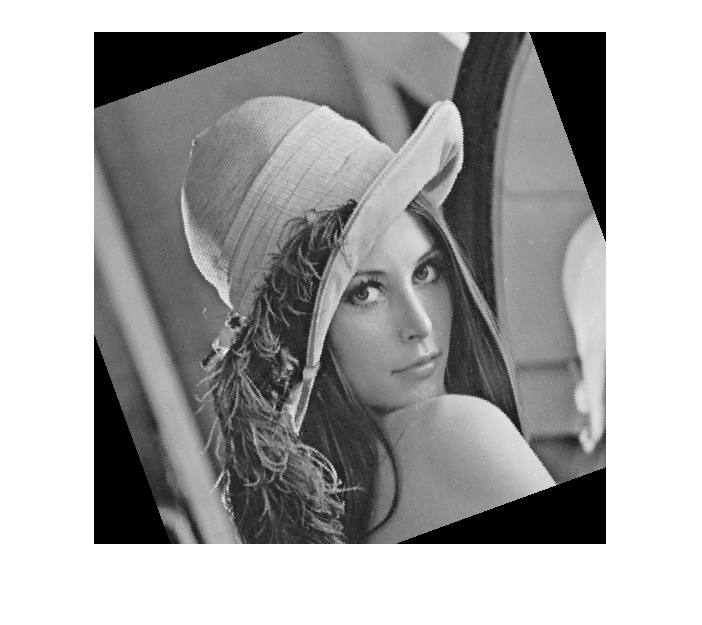

% 图像旋转
% 逆时针20
I2 = imrotate(I1, 20, 'nearest', 'crop');
imshow(I2);

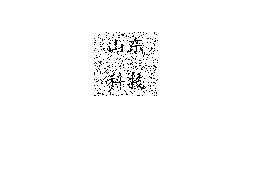

I2 = imrotate(I2, -20, 'nearest', 'crop');
w2 = extract_watermark(I2, key);
imshow(w2);

fprintf('NC: %f\n', nc(w1, w2));

NC: 0.995812


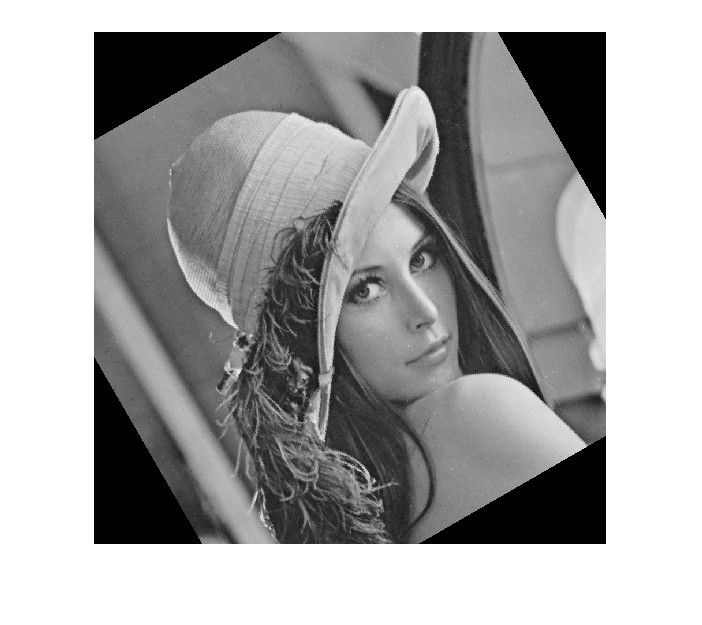

% 逆时针30
I3 = imrotate(I1, 30, 'nearest', 'crop');
imshow(I3);

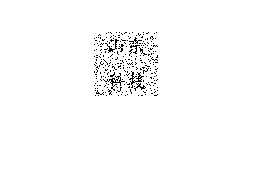

I3 = imrotate(I3, -30, 'nearest', 'crop');
w3 = extract_watermark(I3, key);
imshow(w3);

fprintf('NC: %f\n', nc(w1, w3));

NC: 0.994039


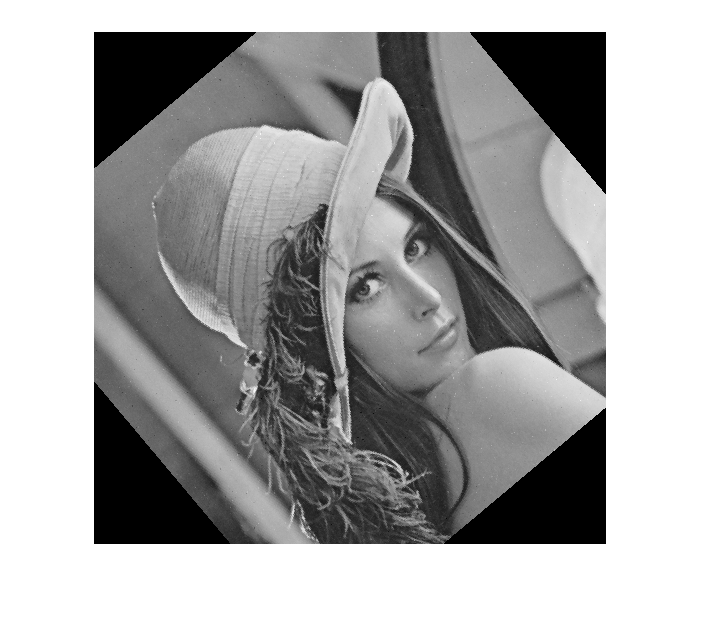

% 逆时针40
I4 = imrotate(I1, 40, 'nearest', 'crop');
imshow(I4);

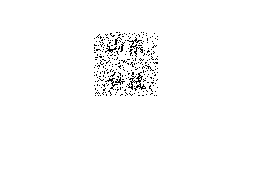

I4 = imrotate(I4, -40, 'nearest', 'crop');
w4 = extract_watermark(I4, key);
imshow(w4);

fprintf('NC: %f\n', nc(w1, w4));

NC: 0.993338


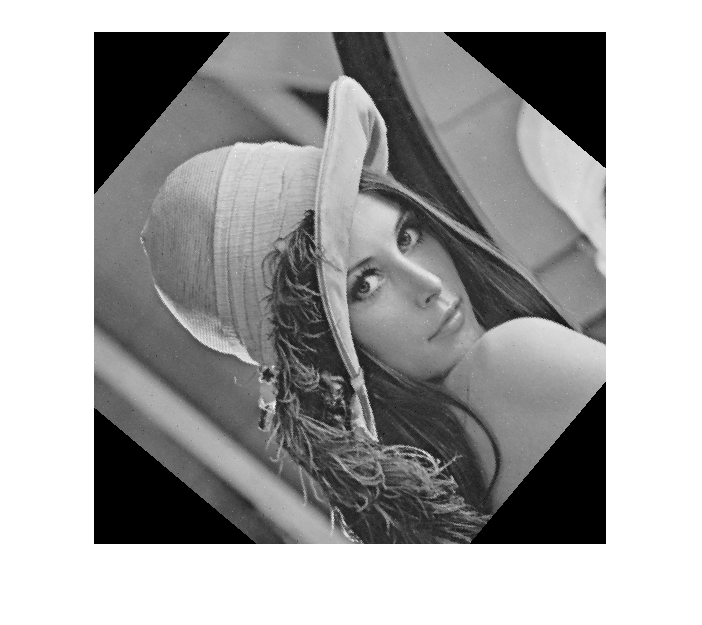

% 逆时针50
I5 = imrotate(I1, 50, 'nearest', 'crop');
imshow(I5);

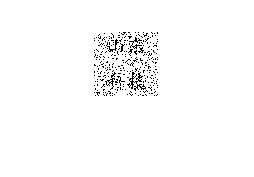

I5 = imrotate(I5, -50, 'nearest', 'crop');
w5 = extract_watermark(I5, key);
imshow(w5);

fprintf('NC: %f\n', nc(w1, w5));

NC: 0.992608


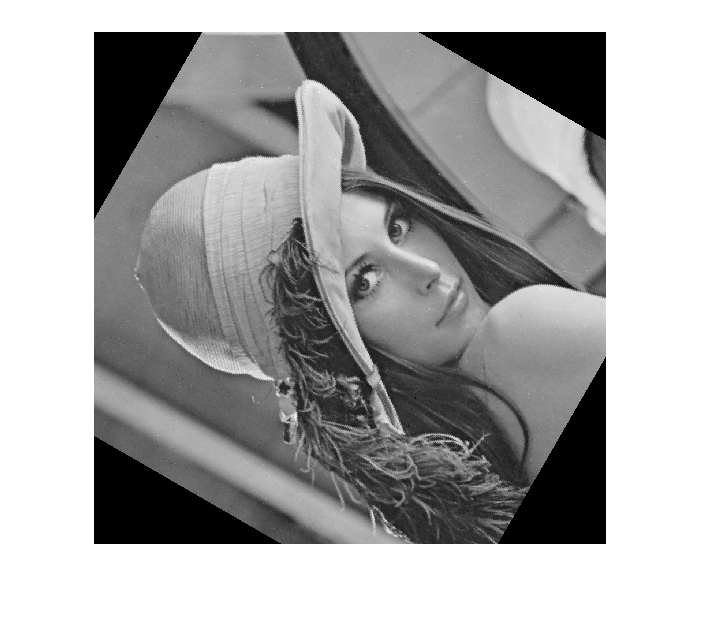

% 逆时针60
I6 = imrotate(I1, 60, 'nearest', 'crop');
imshow(I6);

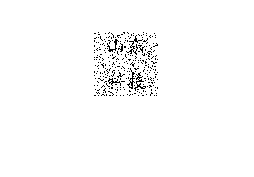

I6 = imrotate(I6, -60, 'nearest', 'crop');
w6 = extract_watermark(I6, key);
imshow(w6);

fprintf('NC: %f\n', nc(w1, w6));

NC: 0.993102


function result = extract_watermark(img, key)
    w = zeros(64, 64);
    % 图像的高度和宽度
    [height, width] = size(img);
    [w_height, w_width] = size(w);
    % 随机数流
    s = RandStream('mt19937ar', 'Seed', sum(uint8(key)), 'NormalTransform', 'Polar');
    % 位置矩阵
    pos = randperm(s, height * width, w_height * w_width);    
    img_enc = encrypt(img, key);
    for i = 1:w_height*w_width
        v = img_enc(pos(i));
        ss = RandStream('mt19937ar', 'Seed', pos(i), 'NormalTransform', 'Polar');
        p = round(4 + (6 - 4) * rand(ss));
        v1 = bitget(v, p + 1);
        v2 = bitget(v, p);
        w(i) = bitxor(v1, v2);
    end
    result = w * 255;
end
function result = embedded_watermark(img, w, key)
    img_enc = encrypt(img, key);
    w = w / 255;
    % 图像的高度和宽度
    [height, width] = size(img_enc);
    [w_height, w_width] = size(w);
    % 随机数流
    s = RandStream('mt19937ar', 'Seed', sum(uint8(key)), 'NormalTransform', 'Polar');
    % 位置矩阵
    pos = randperm(s, height * width, w_height * w_width);
    % 嵌入
    for i = 1:w_height*w_width
        v = img_enc(pos(i));
        ss = RandStream('mt19937ar', 'Seed', pos(i), 'NormalTransform', 'Polar');
        p = round(4 + (6 - 4) * rand(ss));
        v1 = bitget(v, p + 1);
        v2 = bitxor(v1, w(i));
        img_enc(pos(i)) = bitset(v, p, v2);
    end
    % 解密
    result = decrypt(img_enc, key);
end
function result = encrypt(img, key)
    if length(size(img)) ~= 2
        error('图像格式错误');
    end
    key_array = uint8(key);
    if length(key_array) ~= 32
        error('密钥格式错误');
    end
    s = sum(key_array);
    x0 = s / (128 * length(key_array));
    u = 3.99;
    % fprintf('初始值x0=%f\n', x0);
    % fprintf('参数u=%f\n', u);
    [h, w] = size(img);
    c = zeros(1, h * w);
    c(1) = x0;
    for i = 2:h*w
        c(i) = u * c(i - 1) * (1 - c(i - 1));
    end
    c1 = uint8(c * 255);
    M1 = reshape(c1, h, w);
    result1 = bitxor(img, M1);
    s = RandStream('mt19937ar', 'Seed', x0, 'NormalTransform', 'Polar');
    c2 = randperm(s, h * w);
    c3 = zeros(1, h * w);
    for i = 1:h * w
        if c3(i) == 1
            continue;
        end
        if c3(c2(i)) == 1
            continue;
        end
        temp = result1(i);
        result1(i) = result1(c2(i));
        result1(c2(i)) = temp;
        c3(i) = 1;
        c3(c2(i)) = 1;
    end
    result = result1;
end

function result = decrypt(img, key)
    if length(size(img)) ~= 2
        error('图像格式错误');
    end
    key_array = uint8(key);
    if length(key_array) ~= 32
        error('密钥格式错误');
    end
    s = sum(key_array);
    x0 = s / (128 * length(key_array));
    u = 3.99;
    % fprintf('初始值x0=%f\n', x0);
    % fprintf('参数u=%f\n', u);
    [h, w] = size(img);
    c = zeros(1, h * w);
    c(1) = x0;
    for i = 2:h*w
        c(i) = u * c(i - 1) * (1 - c(i - 1));
    end
    c1 = uint8(c * 255);
    M1 = reshape(c1, h, w);
    result1 = img;
    s = RandStream('mt19937ar', 'Seed', x0, 'NormalTransform', 'Polar');
    c2 = randperm(s, h * w);
    c3 = zeros(1, h * w);
    for i = 1:h * w
        if c3(i) == 1
            continue;
        end
        if c3(c2(i)) == 1
            continue;
        end
        temp = result1(i);
        result1(i) = result1(c2(i));
        result1(c2(i)) = temp;
        c3(i) = 1;
        c3(c2(i)) = 1;
    end
    result = bitxor(result1, M1);
end